%1
imgR = [255,0;0 0];
imgG = [0,255;0 0];
imgB = [0,0;255 255];
img = zeros(2,2,3);
img(:,:,1) = imgR;
img(:,:,2) = imgG;
img(:,:,3) = imgB;
img

img = img(:,:,1) =

   255     0
     0     0


img(:,:,2) =

     0   255
     0     0


img(:,:,3) =

     0     0
   255   255


%2(a)
snr = zeros(1,8);
for i=1:8
    img = bucky_images(:,:,i);
    noise = zeros(50,100);
    signalfreearea = bucky_images(300:350,1:100,i);
    stdsignalfree = std(signalfreearea(:));
    snr(i) = mean(mean(img))/stdsignalfree;
end
snr

snr =     4.1879    4.3249    4.3532    5.8625    4.3361    4.2136    4.3574    7.3955


%2(a)
x = snr;
x = sort(x)

x =     4.1879    4.2136    4.3249    4.3361    4.3532    4.3574    5.8625    7.3955


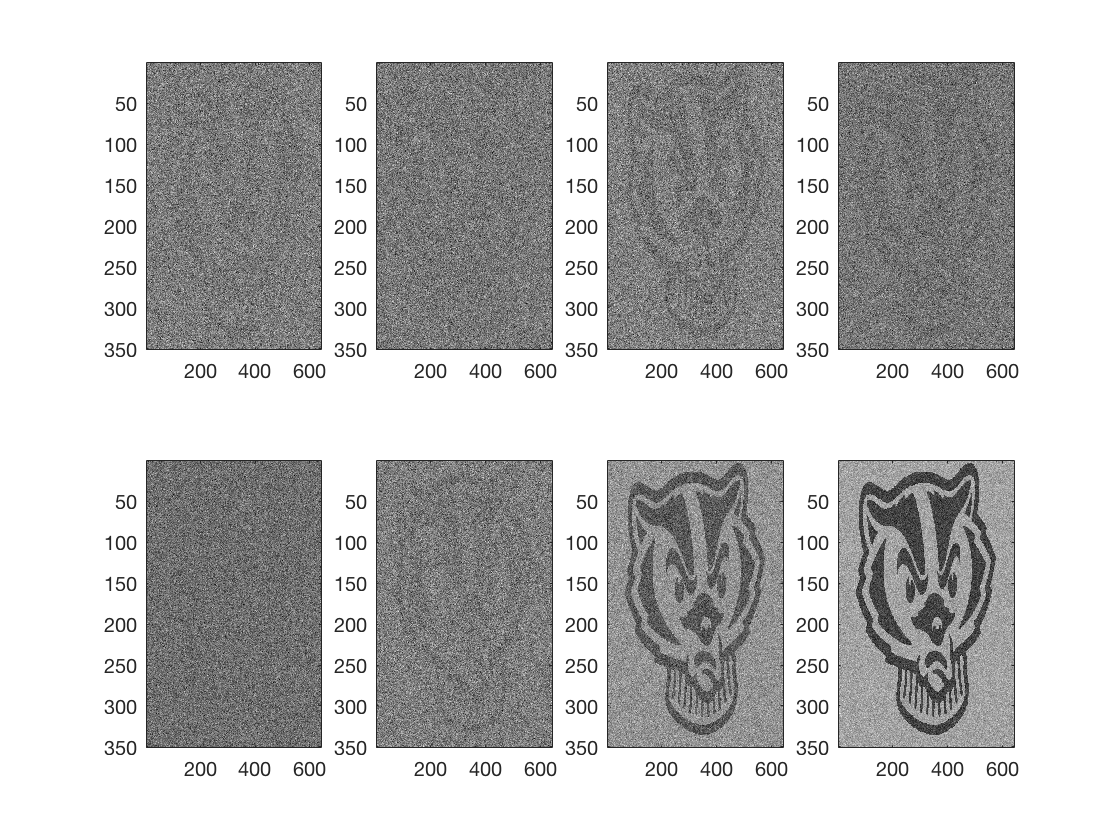

figure
for i=1:8
    subplot(2,4,i)
    img = bucky_images(:,:,find(snr==x(i)));
    minint=min(min(img)); 
    img=img-minint; 
    maxint=max(max(img)); 
    img=img/maxint*63; 
    image(img);
    colormap(gray);
end

%2(c)
cnr = zeros(1,8);
for i=1:8
    img = bucky_images(:,:,i);
    mini = min(min(img));
    maxi = max(max(img));
    noise = zeros(50,100);
    signalfreearea = bucky_images(300:350,1:100,i);
    stdsignalfree = std(signalfreearea(:));
    cnr(i) = (maxi-mini)/stdsignalfree;
end
cnr

cnr =     8.4227    8.6224    9.6647   11.0766    9.1716    8.6662    8.7229   13.5249


x = cnr;
x = sort(x)

x =     8.4227    8.6224    8.6662    8.7229    9.1716    9.6647   11.0766   13.5249


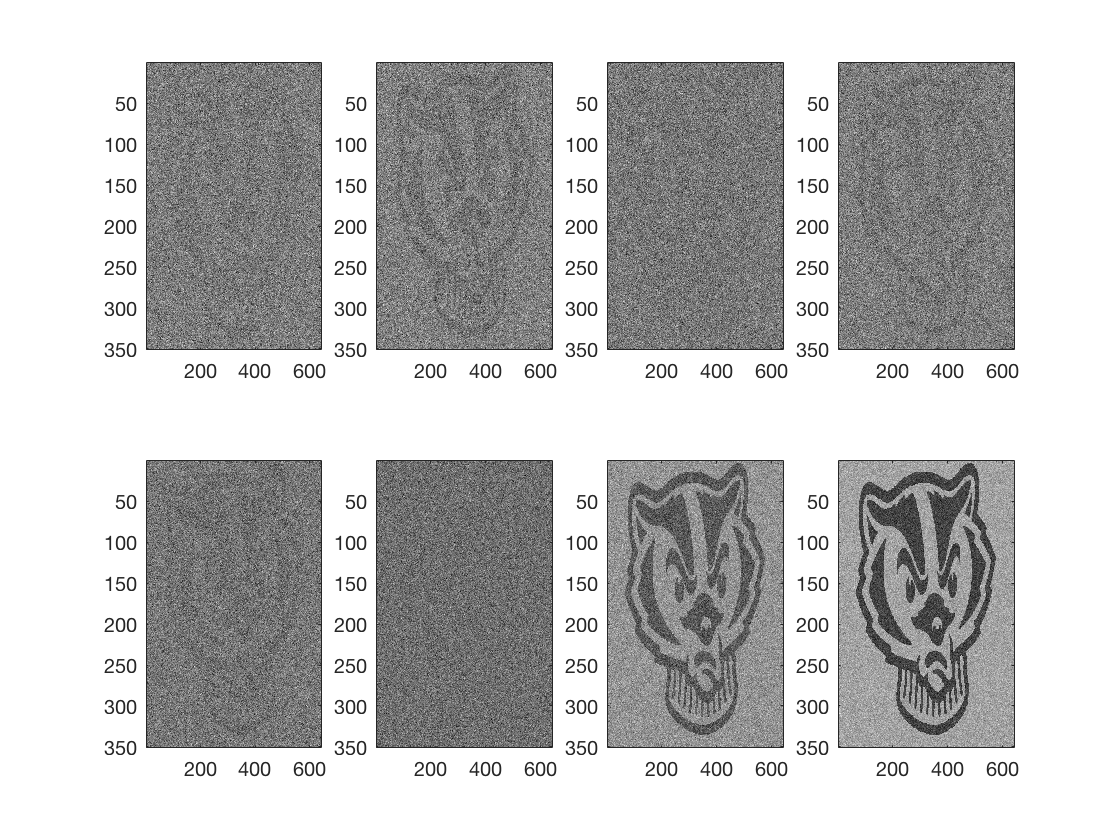

figure
for i=1:8
    subplot(2,4,i)
    img = bucky_images(:,:,find(cnr==x(i)));
    minint=min(min(img)); 
    img=img-minint; 
    maxint=max(max(img)); 
    img=img/maxint*63; 
    image(img);
    colormap(gray);
end


% The order did change. The order changed because the mean of 
% the range of gray values is not good indicator of what the mean 
% of the gray values and if an image has a greater mean then that
% doesn't mean the range is big as well. The range could be really
% small and consist only of big numbers which would 
% make the mean big and thus the numerator of snr and cnr are not
% going to be in the same order.

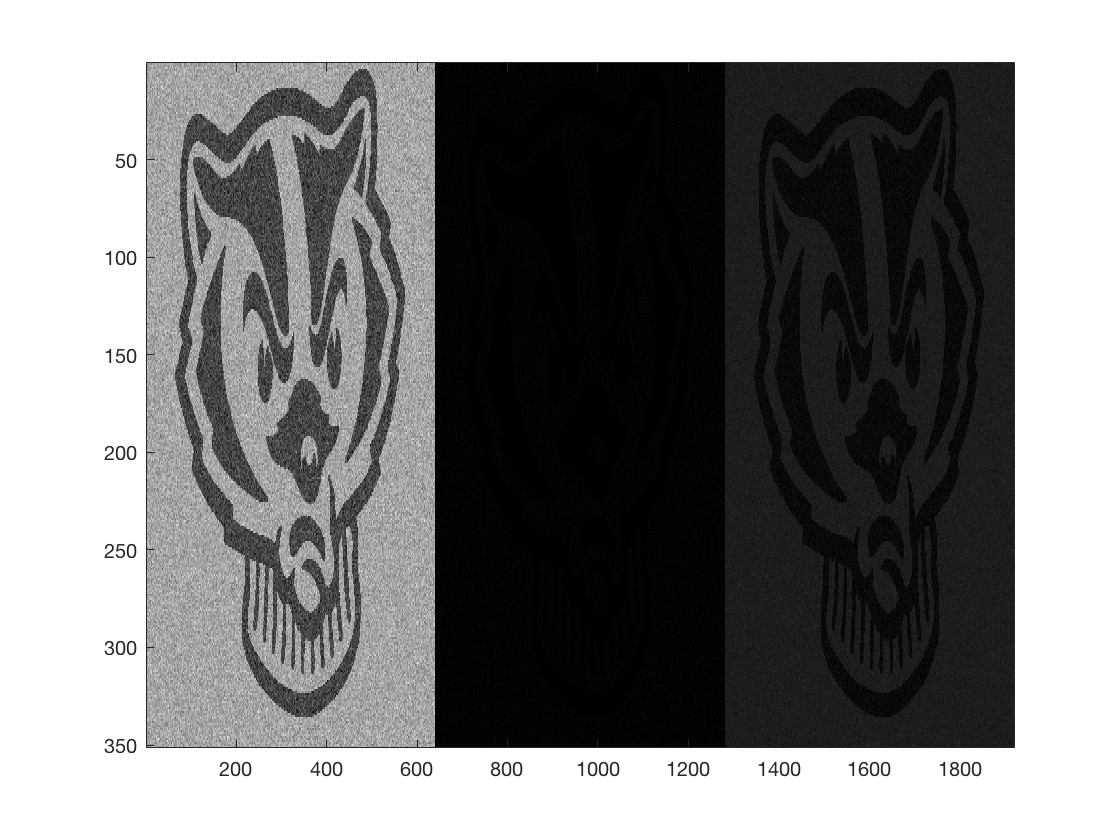

%3(a)
img = bucky_trio;
figure
minint=min(min(img)); 
img = img-minint; 
maxint=max(max(img)); 
img=img/maxint*63; 
image(img);
colormap(gray);

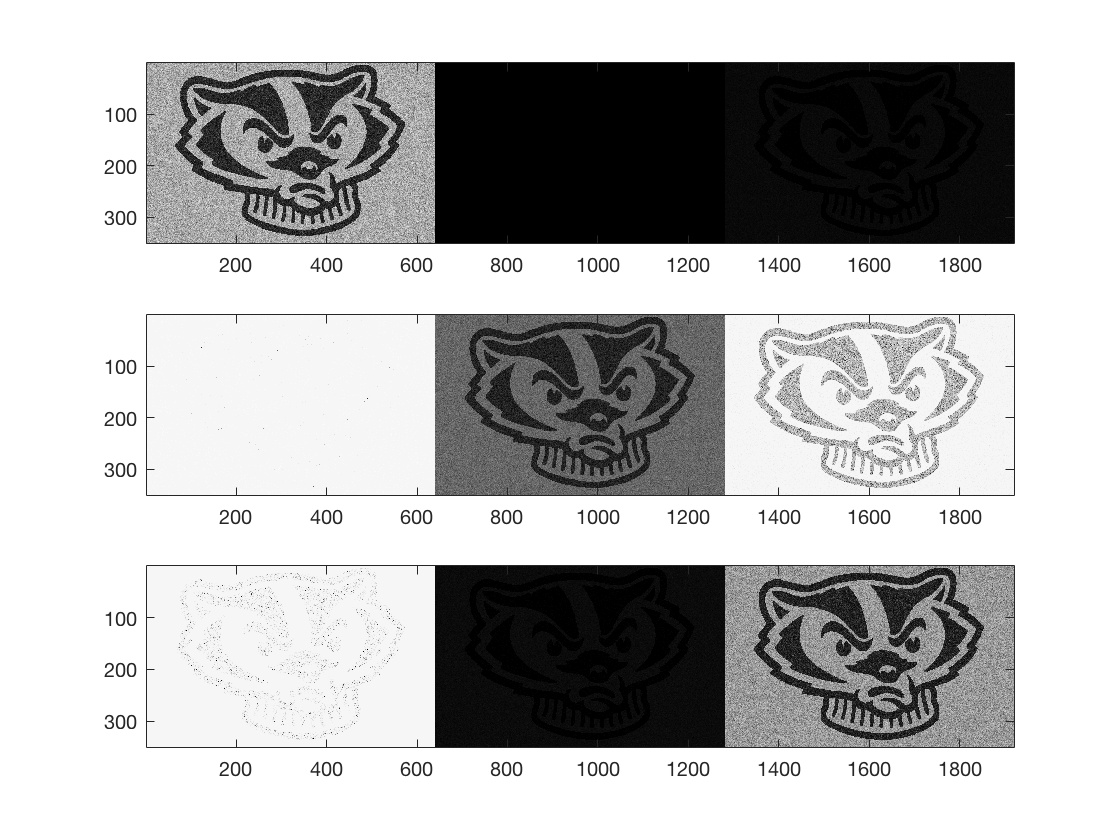

%3(b)

q = bucky_trio(:,1:650);

w = mean(q(:));

s= std(q(:));

img = 63./(1+exp(-1*(bucky_trio -w)/s));

figure
subplot(3,1,1)
minint=min(min(img)); 
img = img-minint; 
maxint=max(max(img)); 
img=img/maxint*63; 
image(img);
colormap(gray); 


q = bucky_trio(:,650:1300);
w = mean(q(:));

s= std(q(:));

img = 63./(1+exp(-1*(bucky_trio -w)/s));

subplot(3,1,2)
minint=min(min(img)); 
img = img-minint; 
maxint=max(max(img)); 
img=img/maxint*63; 
image(img);
colormap(gray); 


q = bucky_trio(:,1300:end);

w = mean(q(:));

s= std(q(:));

img = 63./(1+exp(-1*(bucky_trio -w)/s));

subplot(3,1,3)
minint=min(min(img)); 
img = img-minint; 
maxint=max(max(img)); 
img=img/maxint*63; 
image(img);

colormap(gray);

%3(c)
%In the previous part, I found the mean and standard deviations
%for each seperate portion of the image and used the sigmoid function  
% to focus most of the available range to the intensities most 
% frequent in that portion of the image. This caused the other portions
% to either become much darker and close to black or much lighter and close
% to white. This is because the intensities that weren't within a standard
% deviation of the mean were pushed to either the upper values of the range
% or the lower values of the range and thus almost all pixels in those
% portions either became light or dark since a very little portion of the
% range covered the intensities in that portion. Because of this little range
% there wasn't sufficient contrast and the portions were almost fully
% dark or fully white.

%4
retina = imread('/Users/utkarsh/Documents/MATLAB/CS567/HW2/distributed/img_029.ppm');
z=retina;
z = 0.1*z(:,:,1) + 1.5*z(:,:,2) + 0.1*z(:,:,3);
a = 200;
b= 250;

%4(a)I chose my windowing parameters by looking at the specific part of the
%image that had the spots and realizing that since the spots are bright,
%the window should focus on the higher intensity values so that the spots can 
%stand out.
a

a = 200

b

b = 250

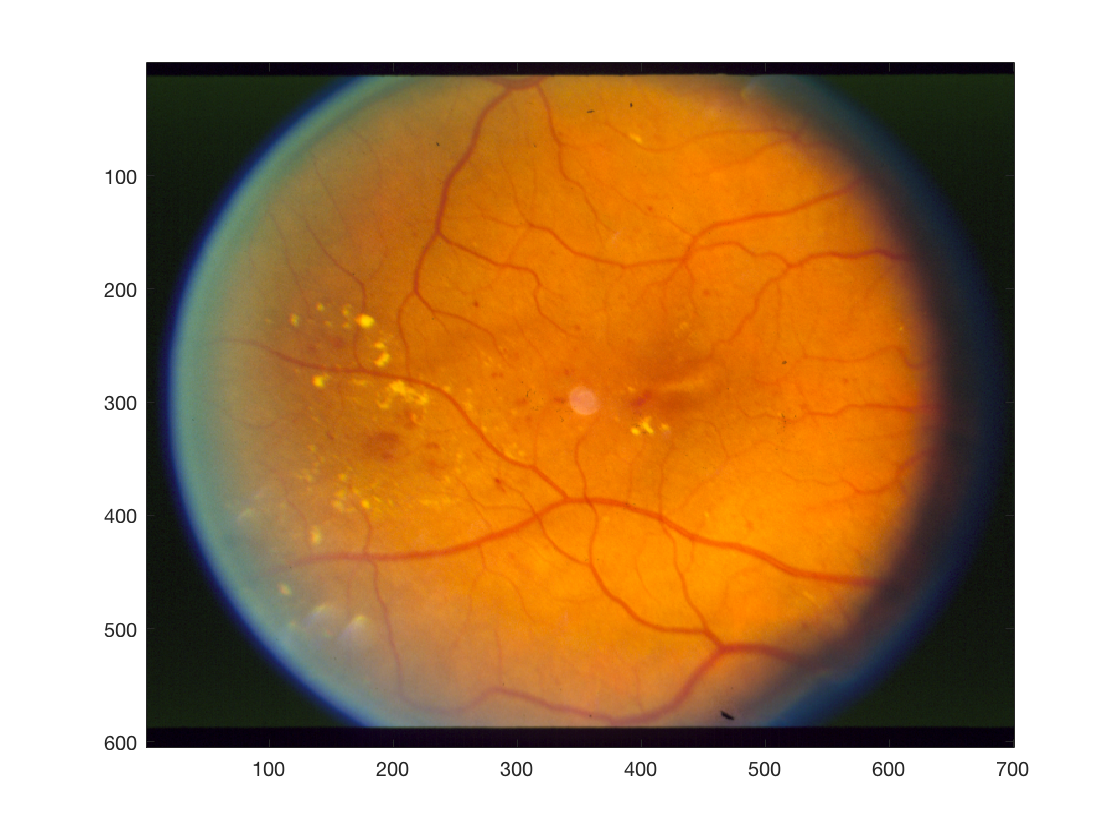


%%4(b) I chose the weights for the grayscale because after looking at the
%%the seperate color channels, I realized that the spots were most
%%prominent and also had the greatest contrast with everything else in
%in the blue channel while in the red channel, the spots were bright
%but other portions were just as bright so a higher weight would also bring
%out the other sections. So I decided to use small weights for the red and blue 
%channel and assigned a relatively high weight to the green channel.

%4(c)
z(z<a) = 0;
z(z>b) = 255;
z(z>=a & z<=b) = (255/(b-a))*z(z>=a & z<=b) - 255*a/(b-a);
figure 
imagesc(retina)

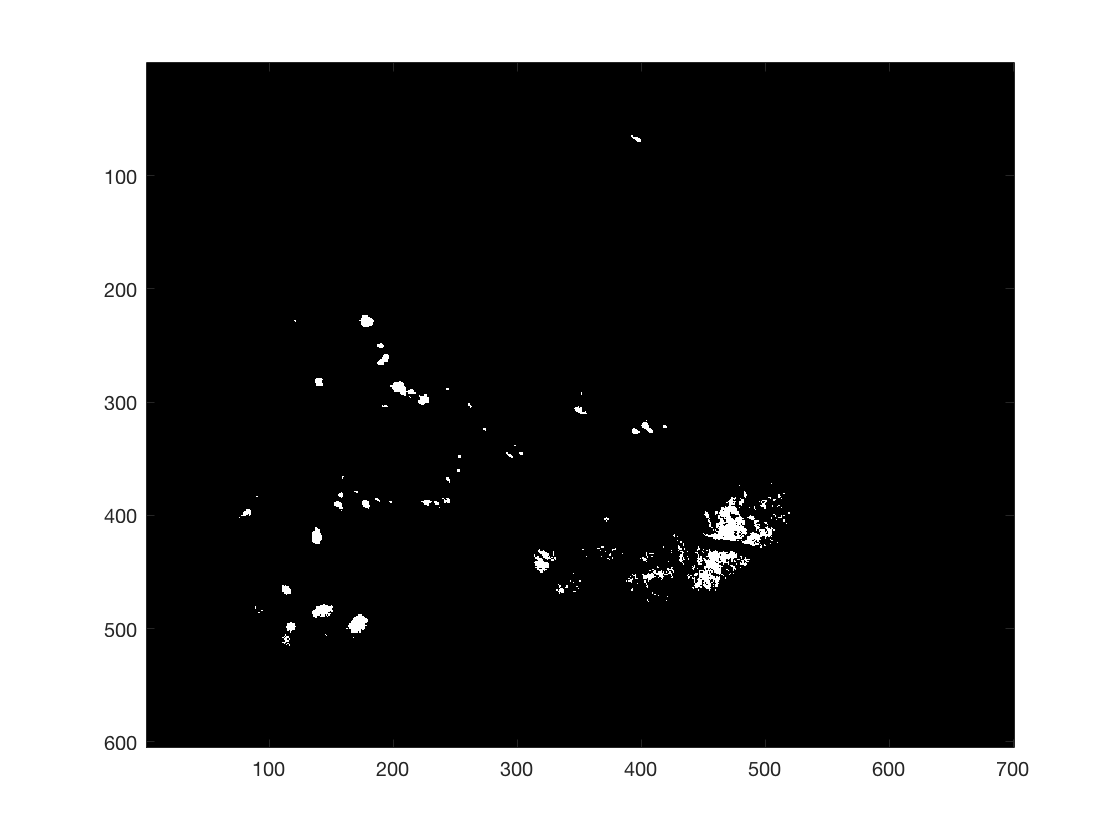

figure
imin=min(min(z));
z=z-imin;
imax=max(max(z));
z= z/imax*63; 
image(z)
colormap(gray)

%%5(a)
% script from W. Birkfellner, M. Figl, J. Hummel: "Medical Image Processing - A Basic Course", copyright 2010 by Taylor & Francis
clear;
fp=fopen('/Users/utkarsh/UW-Mad Courses/CS567BookStuff/LessonData/5_Filtering/SKULLBASE.DCM', 'r'); 
fseek(fp,1622,'bof'); 
img=zeros(512,512); 
img(:)=fread(fp,(512*512),'short'); 
img=transpose(img); 
fclose(fp);
diffimg=zeros(512,512);
for i=1:511 
for j=1:511 
diffimg(i,j) = -img(i,j) + img(i+1,j); 
end 
end 


convmat = zeros(3,3);
convmat(1,2) = 1;
convmat(2,2) = -1;

convmat

convmat =      0     1     0
     0    -1     0
     0     0     0


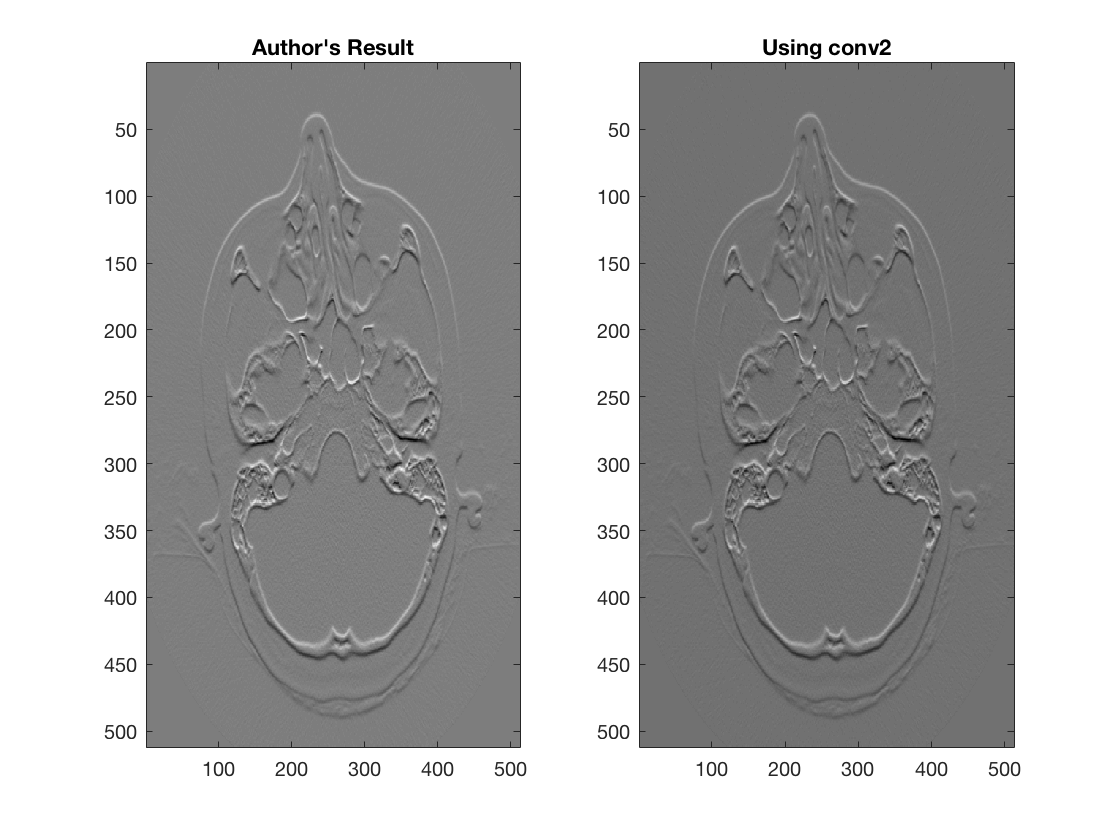

convout = conv2(img, convmat, 'same');

figure
subplot(1,2,1)
minint=min(min(diffimg)); 
diffimg=diffimg-minint; 
maxint=max(max(diffimg)); 
diffimg=diffimg/maxint*63; 
colormap(gray); 
image(diffimg)
title("Author's Result")
subplot(1,2,2)
minint=min(min(convout)); 
convout=convout-minint; 
maxint=max(max(convout)); 
convout=convout/maxint*63; 
image(convout)
colormap(gray); 
title("Using conv2")

%%5(b)
% script from W. Birkfellner, M. Figl, J. Hummel: "Medical Image Processing - A Basic Course", copyright 2010 by Taylor & Francis
clear;
fp=fopen('/Users/utkarsh/UW-Mad Courses/CS567BookStuff/LessonData/5_Filtering/SKULLBASE.DCM', 'r'); 
fseek(fp,1622,'bof'); 
img=zeros(512,512); 
img(:)=fread(fp,(512*512),'short'); 
img=transpose(img); 
fclose(fp);
diffimg=zeros(512,512);
for i=1:511 
for j=1:511 
diffimg(i,j) = -img(i,j) + img(i,j+1); 
end 
end 


convmat = zeros(3,3);
convmat(2,1) = 1;
convmat(2,2) = -1;

convmat

convmat =      0     0     0
     1    -1     0
     0     0     0


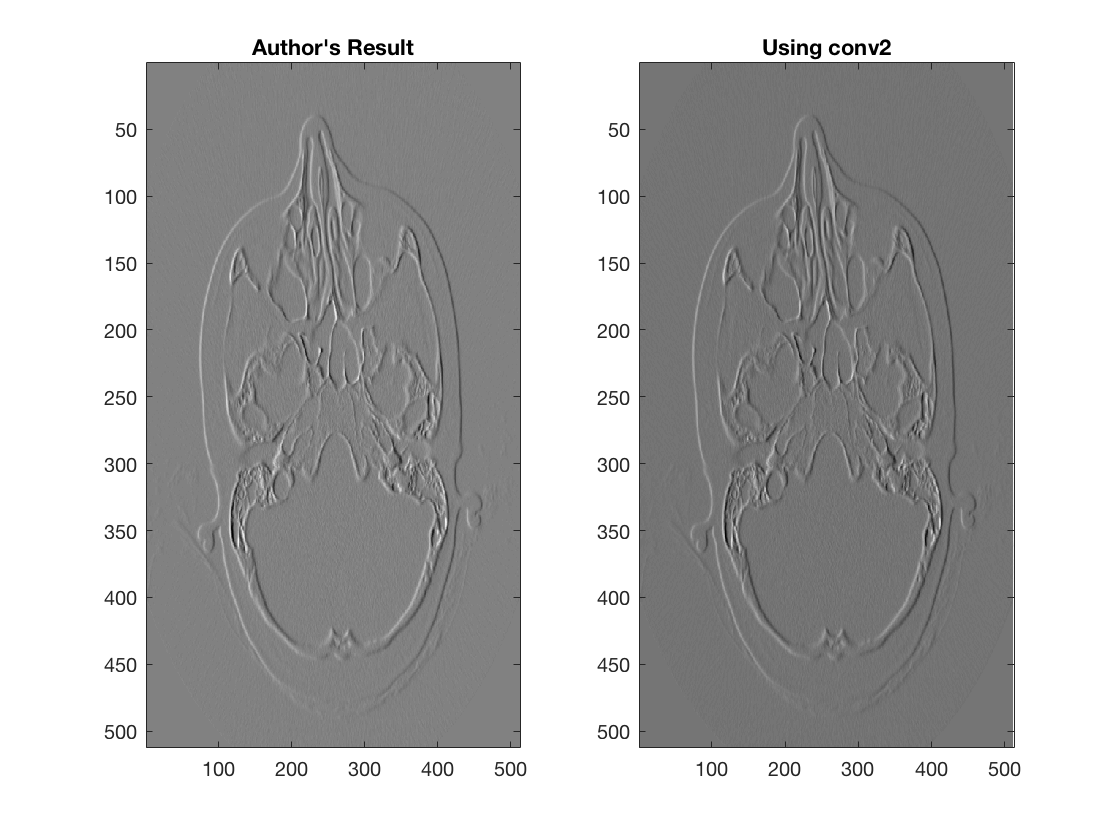

convout = conv2(img, convmat, 'same');

figure
subplot(1,2,1)
minint=min(min(diffimg)); 
diffimg=diffimg-minint; 
maxint=max(max(diffimg)); 
diffimg=diffimg/maxint*63; 
colormap(gray); 
image(diffimg)
title("Author's Result")
subplot(1,2,2)
minint=min(min(convout)); 
convout=convout-minint; 
maxint=max(max(convout)); 
convout=convout/maxint*63; 
colormap(gray); 
image(convout)
title("Using conv2")

%5(c)

ky = zeros(3,3);
ky(2,1) = 1;
ky(2,3) = -1;
ky = 0.5*ky;

kx = zeros(3,3);
kx(1,2) = 1;
kx(3,2) = -1;
kx = 0.5*kx;

kx

kx =          0    0.5000         0
         0         0         0
         0   -0.5000         0


ky

ky =          0         0         0
    0.5000         0   -0.5000
         0         0         0


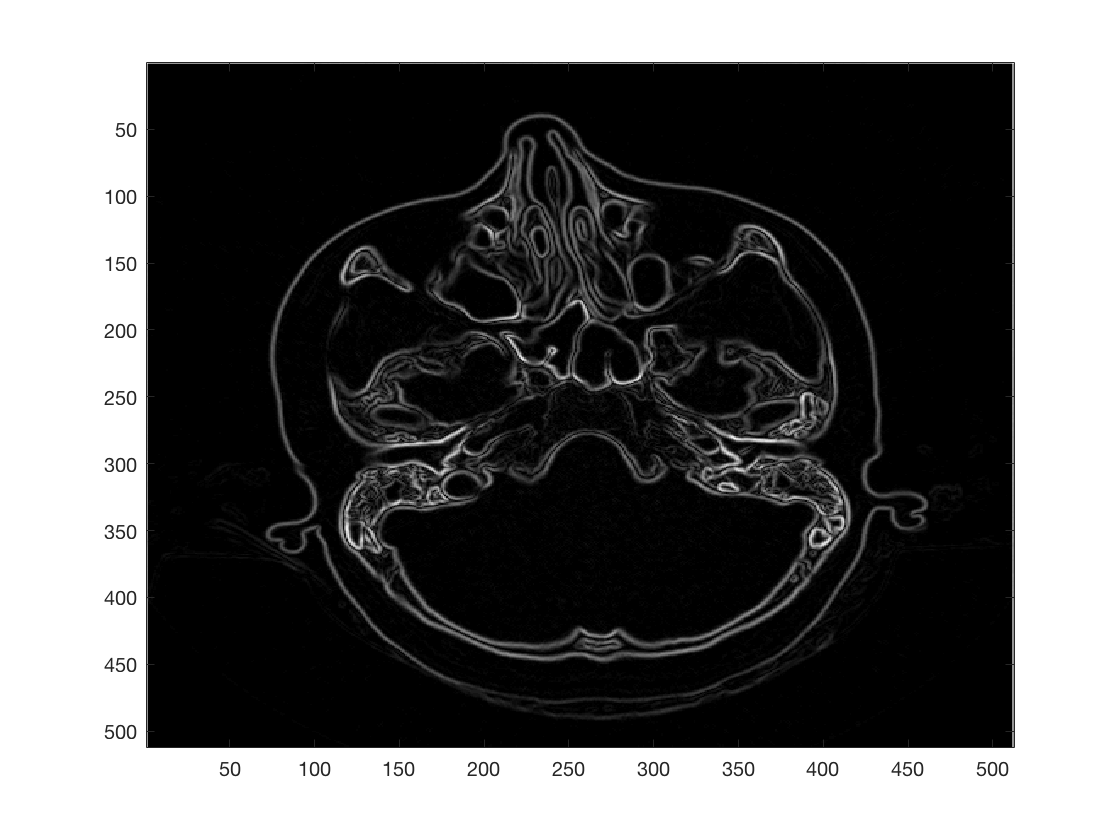


x = conv2(img, kx, 'same');
y = conv2(img, ky, 'same');

gradlength = sqrt(x.^2 + y.^2);

figure
minint=min(min(gradlength)); 
gradlength=gradlength-minint; 
maxint=max(max(gradlength)); 
gradlength=gradlength/maxint*63; 
colormap(gray); 
image(gradlength)